## Sound insulation of a single leaf wall

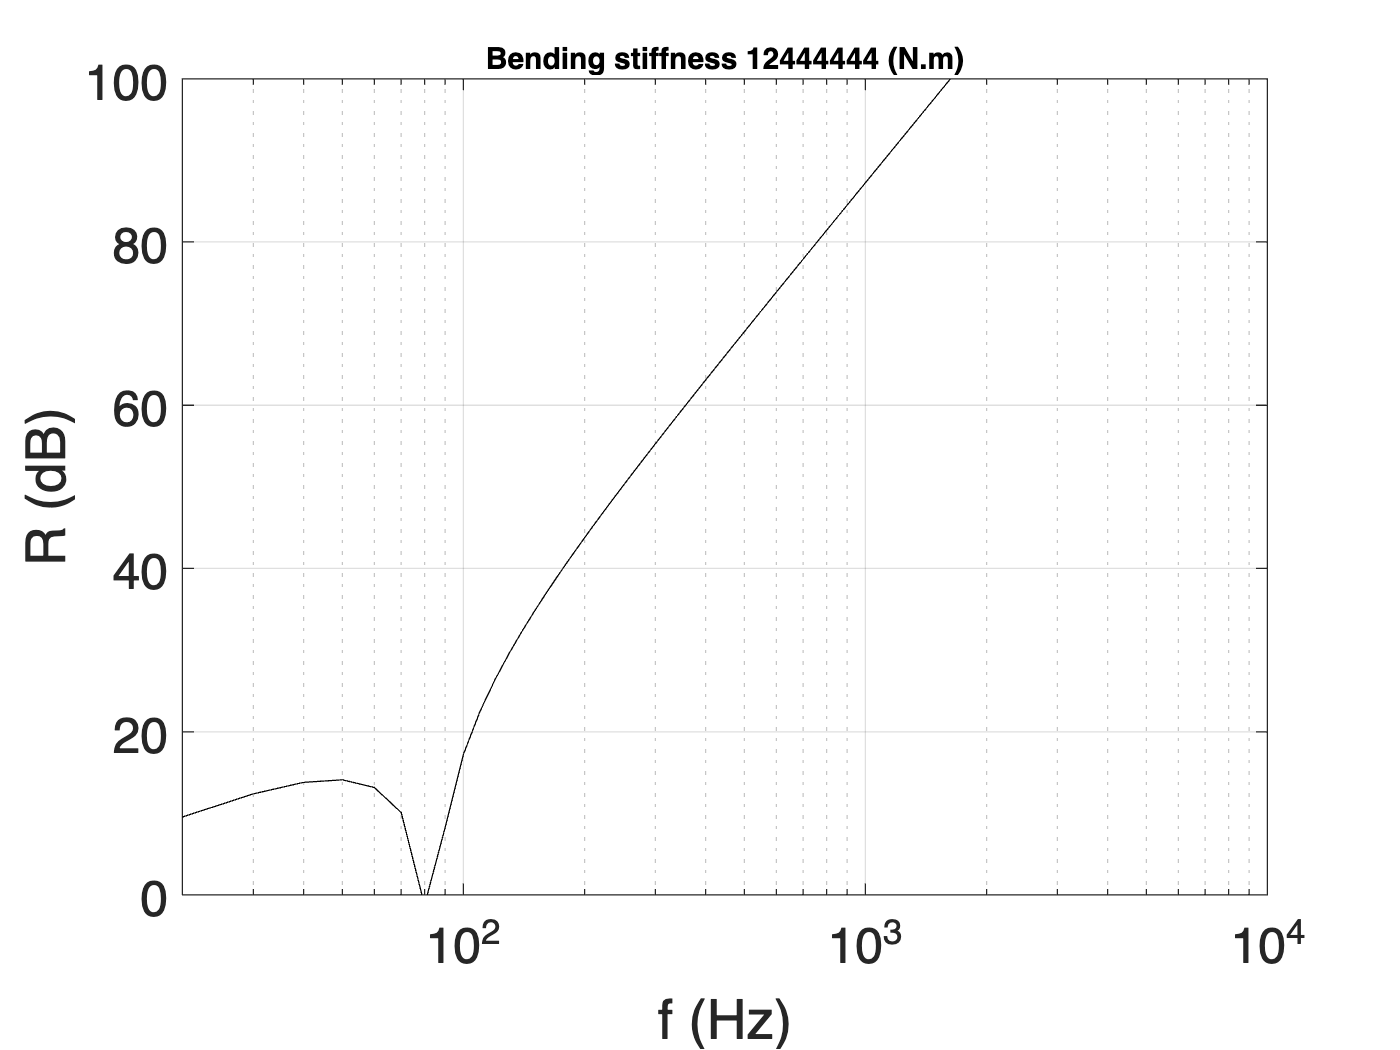

fmax       =   10000;       %   max frequency (Hz)
angle      =   85;       % angle of incidence (deg)
md         = 1500;        % density of panel (kg/m3)
d          =  0.16;      % thickness of panel (m)

soundinsulationsingle(fmax,angle,md,d)

### Help functions

Feel free to modify to make it better!

function soundinsulationsingle(fmax,angle,md,d)

fv = 10:10:fmax;
omega = 2.*pi.*fv;
rho = 1.2;
c = 343;            % speed of sound (m/s)
Z0 = rho.*c;        % impedance of air (kg/s.m^2)
Y = 3.5e10;       % Youngs modulus concrete (Pa)
mue = 0.2;        % Poisson's ratio concrete (-)     
mp = md.*d;         % mass per square meter (kg/m^2)
B = d.^3./12.*Y./(1-mue.^2);    % Bending stiffness (N.m)
X = omega.*mp./(2.*Z0).*cos(angle.*pi./180).*(1-(B.*omega.^2.*(sin(angle.*pi./180).^4))./(mp.*c^4));
R = 10.*log10(X.^2);    % sound insulation (dB)

close all
figure(11)
semilogx(fv,R,'k')
xlabel(['f (Hz)'],'FontSize',20)
ylabel(['R (dB)'],'FontSize',20)
set(gca,'FontSize',20)
title(['Bending stiffness ',num2str(round(B)),' (N.m)'],'FontSize',12)
grid on
axis([20 fmax 0 100])
box on

end
